# Actividad 8.1 (SLAM de Lidar)

Bruno Manuel Zamora Garcia A01798275

**Introducción**

En esta práctica se vera cómo la variación de los diferentes parámetros clave impacta el desempeño de un robot diferencial al seguir trayectorias en un mapa de navegación con obstáculos . Ajustando el tiempo de muestreo, la configuración del sensor LIDAR y las propiedades del controlador Pure Pursuit, como la distancia de anticipación y las velocidades máximas, se logra evaluar la precisión, la estabilidad y el tiempo total de recorrido. Asimismo, se integra el algoritmo Vector Field Histogram (VFH) para garantizar una evasión de obstáculos fluida. El análisis permite identificar combinaciones de valores que optimizan el balance entre velocidad, suavidad de la trayectoria y seguridad en espacios de distinta complejidad.

**1. Sample Time (**`sampleTime`**) y Vector de Tiempo (**`tVec`**)**

- **Efecto de **`sampleTime`**:**

- *Menor valor* (por ejemplo 0.05 s) aumenta la frecuencia de cálculo de control, mejorando la suavidad de la trayectoria y la precisión en curvas cerradas, pero incrementa el uso de CPU y la latencia de visualización.

- *Mayor valor* (por ejemplo 0.2 s) reduce la carga computacional, pero puede provocar “saltos” en la estimación de pose y errores en giros, especialmente con velocidades altas.

- **Longitud de **`tVec`**:**

- Define el tiempo máximo de simulación. Si es muy corto, el robot puede no alcanzar el destino y detenerse prematuramente. Si es muy extenso, la simulación continúa aún cuando el robot ya haya llegado, consumiendo recursos inútilmente.

**2. Pose Inicial (**`initPose`**)**

- La ubicación y orientación de partida condicionan el recorrido total:

- Un *initPose* cercano al primer waypoint reduce la trayectoria, ahorrando tiempo.

- Variar el ángulo inicial (θ) influye en la maniobra inicial: orientaciones desfavorables pueden requerir giros bruscos, penalizando el trazado y aumentando el tiempo de llegada.

**3. Configuración del LIDAR (**`scanAngles`** y **`maxRange`**)**

- **Resolución Angular (**`scanAngles`**):**

- Muchos ángulos (por ejemplo 360 lecturas) detectan obstáculos con precisión milimétrica pero ralentizan el bucle de sensado.

- Menos ángulos (por ejemplo 90 lecturas) reducen la carga, pero pueden “perder” obstáculos pequeños o estrechos.

- **Alcance Máximo (**`maxRange`**):**

- Un *maxRange* alto (≥3 m) permite anticipar obstáculos lejanos, útil en espacios amplios.

- Un *maxRange* bajo (≤1 m) reduce la detección temprana, volviéndose inseguro en pasillos largos.

**4. Definición de Waypoints**

- **Cantidad y Distribución:**

- Waypoints cercanos entre sí producen trayectorias más rectas y segmentadas, facilitando el seguimiento pero aumentando el número de paradas intermedias.

- Waypoints muy espaciados fuerzan trayectorias curvas amplias; el controlador puede desviarse más de la ruta óptima entre puntos.

**5. Parámetros del Controlador Pure Pursuit**

- **Lookahead Distance (**`controller.LookaheadDistance`**):**

- *Valores pequeños* (<0.2 m) generan giros más agresivos para corregir rápido la ruta, ideales en pasillos estrechos, pero propician oscilaciones (“zig-zag”).

- *Valores grandes* (>0.5 m) suavizan la trayectoria en curvas amplias, reduciendo oscilaciones, pero aumentan el error de seguimiento en espacios cerrados.

- **Desired Linear Velocity (**`controller.DesiredLinearVelocity`**):**

- Velocidades bajas (<0.5 m/s) mejoran el control fino y la estabilidad en trayectorias complejas, aunque extienden el tiempo total.

- Velocidades altas (>1 m/s) aceleran el recorrido en entornos despejados, pero pueden provocar sobrepasos de waypoints y dificultar la evasión puntual de obstáculos.

- **Max Angular Velocity (**`controller.MaxAngularVelocity`**):**

- Limitaciones suaves (≤5 rad/s) evitan giros bruscos que desestabilicen el robot o provoquen colisiones.

- Permitir valores muy altos (≥10 rad/s) ofrece gran maniobrabilidad, pero con riesgo de pérdida de tracción o lecturas erráticas del LIDAR durante el giro.

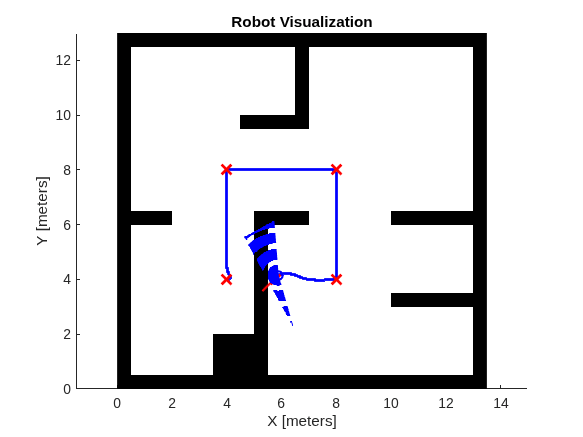

%% Simulación 1

figure('Name','Simulación 1','NumberTitle','off')
% Parámetros del robot
R     = 0.05;  L = 0.18;
dd    = DifferentialDrive(R,L);

% Muestreo y tiempos
sampleTime = 0.1;
tVec       = 0:sampleTime:80;

% Pose inicial
initPose = [4;4;0];
pose     = zeros(3,numel(tVec));
pose(:,1)= initPose;

% Mapa y LIDAR
load exampleMap
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles   = linspace(-pi,pi,360);
lidar.maxRange     = 2;

% Visualizador
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName       = 'map';
attachLidarSensor(viz,lidar);

% Waypoints
waypoints = [initPose(1:2)';
             4,8;
             8,8;
             8,4;
             5.8,4];

% Controlador Pure Pursuit
controller = controllerPurePursuit;
controller.Waypoints           = waypoints;
controller.LookaheadDistance   = 0.2;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity    = 5;

% VFH para evasión
vfh = controllerVFH;
vfh.DistanceLimits     = [0.05 3];
vfh.NumAngularSectors  = 900;
vfh.HistogramThresholds= [5 10];
vfh.RobotRadius        = L;
vfh.SafetyDistance     = L;
vfh.MinTurningRadius   = 0.1;

% Bucle de simulación
r = rateControl(1/sampleTime);
for k = 2:numel(tVec)
    cur    = pose(:,k-1);
    ranges = lidar(cur);
    [vRef,wRef,lookPt] = controller(cur);
    dirDes = atan2(lookPt(2)-cur(2), lookPt(1)-cur(1)) - cur(3);
    steer  = vfh(ranges, lidar.scanAngles, dirDes);
    if ~isnan(steer) && abs(steer-dirDes)>0.2
        wRef = 0.3*steer;
    end
    velB = [vRef;0;wRef];
    vel  = bodyToWorld(velB,cur);
    pose(:,k) = cur + vel*sampleTime;
    viz(pose(:,k),waypoints,ranges)
    waitfor(r);
    if norm(pose(1:2,k)-waypoints(end,:)')<0.2, break; end
end

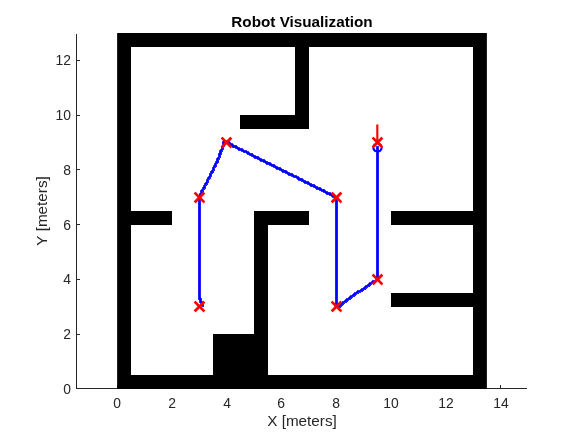



%% Simulación 2

figure('Name','Simulación 2','NumberTitle','off')
% (Los parámetros R,L,sampleTime,scanAngles,maxRange y vfh ya están definidos arriba)

% Tiempo y pose inicial
tVec     = 0:sampleTime:80;
initPose = [3;3;0];
pose     = zeros(3,numel(tVec));
pose(:,1)= initPose;

% Mapa y LIDAR
load exampleMap
lidar.scanAngles = linspace(-pi,pi,360);
lidar.maxRange   = 2;

% Visualizador
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName      = 'map';
attachLidarSensor(viz,lidar);

% Nuevos waypoints
waypoints = [initPose(1:2)';
             3,7;
             4,9;
             8,7;
             8,3;
             9.5,4;
             9.5,9];

% Ajuste del controlador
controller.Waypoints             = waypoints;
controller.LookaheadDistance     = 0.2;
controller.DesiredLinearVelocity = 0.6;
controller.MaxAngularVelocity    = 7;

% Bucle de simulación
r = rateControl(1/sampleTime);
for k = 2:numel(tVec)
    cur    = pose(:,k-1);
    ranges = lidar(cur);
    [vRef,wRef,lookPt] = controller(cur);
    dirDes = atan2(lookPt(2)-cur(2), lookPt(1)-cur(1)) - cur(3);
    steer  = vfh(ranges, lidar.scanAngles, dirDes);
    if ~isnan(steer) && abs(steer-dirDes)>0.2
        wRef = 0.3*steer;
    end
    velB = [vRef;0;wRef];
    vel  = bodyToWorld(velB,cur);
    pose(:,k) = cur + vel*sampleTime;
    viz(pose(:,k),waypoints,ranges)
    waitfor(r);
    if norm(pose(1:2,k)-waypoints(end,:)')<0.2, break; end
end

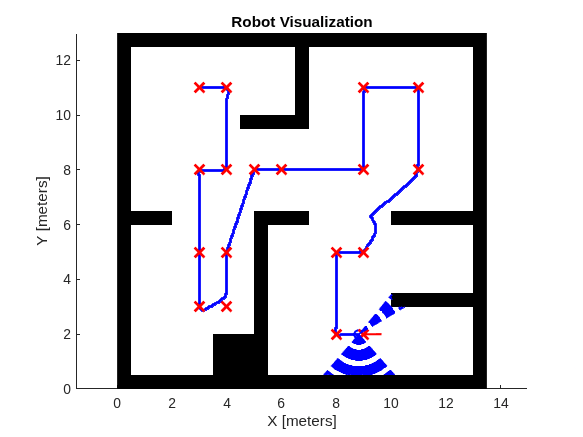



%% Simulación 3

figure('Name','Simulación 3','NumberTitle','off')
tVec     = 0:sampleTime:150;
initPose = [3;11;0];
pose     = zeros(3,numel(tVec));
pose(:,1)= initPose;

load exampleMap
lidar.scanAngles = linspace(-pi,pi,360);
lidar.maxRange   = 2;

viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName      = 'map';
attachLidarSensor(viz,lidar);

waypoints = [initPose(1:2)';
             4,11;4,8;3,8;
             3,5;3,3;4,3;
             4,5;5,8;6,8;
             9,8;9,11;11,11;
            11,8;9,5;8,5;
             8,2;9,2];

controller.Waypoints             = waypoints;
controller.LookaheadDistance     = 0.2;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity    = 5;

r = rateControl(1/sampleTime);
for k = 2:numel(tVec)
    cur    = pose(:,k-1);
    ranges = lidar(cur);
    [vRef,wRef,lookPt] = controller(cur);
    dirDes = atan2(lookPt(2)-cur(2), lookPt(1)-cur(1)) - cur(3);
    steer  = vfh(ranges, lidar.scanAngles, dirDes);
    if ~isnan(steer) && abs(steer-dirDes)>0.2
        wRef = 0.3*steer;
    end
    velB = [vRef;0;wRef];
    vel  = bodyToWorld(velB,cur);
    pose(:,k) = cur + vel*sampleTime;
    viz(pose(:,k),waypoints,ranges)
    waitfor(r);
    if norm(pose(1:2,k)-waypoints(end,:)')<0.2, break; end
end